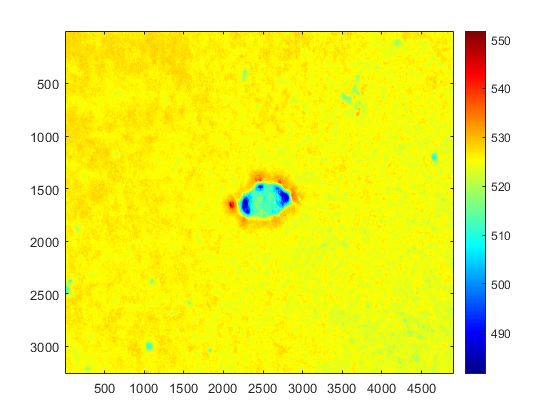

% Program initialization. Load the mapping relationship between hue and wavelength.
load Hue_Wavelength_Mapping.mat

% Display a GUI dialog for the user to select a PCCFM TIFF image file.
[file, path] = uigetfile('*.tif', 'Please select a TIFF image file');
if isequal(file,0)
   disp('Canceled');
   return
end
filepath = fullfile(path,file);
im=double(imread([path,file]));
im_hsv=rgb2hsv(im);

% Iteratively retrieve the corresponding wavelength for each pixel.
[r,c,d]=size(im_hsv);
im_wavelength=zeros(r,c);

parfor i=1:r
    for j=1:c
         [~, n] = min(abs(checktable-im_hsv(i,j,1)));
        im_wavelength(i,j)=wlmax-double(n)/10;
    end
end

% Display the results
figure
imagesc(im_wavelength)
colormap jet
colorbar